clear ;
close all;

bTrainingWithValidation = true;
load ryan2_gen_data.mat

머신러닝 방법을 사용하기 위해 데이타 정규화.

이때 test set 에서도 동일한 범위로 동작하기 위해 모든 데이타에 대해 한번에 정규화해야 함.

ynorm,xnorm = training set

ytestnorm,xtestnorm = test set

idx = idxAll;
y = [battery_dataset(idx).cycle_life ]';
x = (reshape([battery_dataset(idx).Ic],100,length(y)))';
[ynormall,ymax,ymin,yrate,xnormall,xmax,xmin,xrate] = minmax_norm_all(y,x);


%%% LSTM 회귀
%idx = idxAll; %RMSE = 1032  - 잘 동작
idx = idx12 ; % training set - 
idxtest = idx3 ; % training set - 
%idx = idx1;
key = [battery_dataset(idx).key]';
% s1 = string([{battery_dataset(idx).policy}])
% policy = [{battery_dataset(idx).policy}]';
% policy_str = string([{battery_dataset(idx).policy}]');
% policy_readable = [{battery_dataset(idx).policy_readable}]';
% policy_readable_str = string([{battery_dataset(idx).policy_readable}]');
%Ic1 = [{battery_dataset(idx).Ic}]';
%Ic_ = [battery_dataset(idx).Ic];
%Ic__ = reshape(Ic_,100,length(policy));
%Ic = Ic__';
y = [battery_dataset(idx).cycle_life ]';
x_input_size = 100;
x = (reshape([battery_dataset(idx).Ic],x_input_size,length(y)))';

keytest = [battery_dataset(idxtest).key]';
ytest = [battery_dataset(idxtest).cycle_life ]';
xtest = (reshape([battery_dataset(idxtest).Ic],x_input_size,length(ytest)))';

[ynorm,xnorm] = norm_with(y,x,ymax,ymin,xmax,xmin);
[ytestnorm,xtestnorm] = norm_with(ytest,xtest,ymax,ymin,xmax,xmin);

% xnorm = x;
% ynorm = y;
% Test_Input = xtest;
% Test_Output = ytest;

FNN 으로 테스트 - training set (test/validation 없이 )

feedforwardnet([50,10] => 2개충, 첫번째 50 뉴런, 두번째층 10 개 뉴런

=== 참조 ==

`hiddenSizes` **—** **Size of the hidden layers**

10 (default) | row vector

Size of the hidden layers in the network, specified as a row vector. The length of the vector determines the number of hidden layers in the network.

**Example:** For example, you can specify a network with 3 hidden layers, where the first hidden layer size is 10, the second is 8, and the third is 5 as follows: `[10,8,5]`

The input and output sizes are set to zero. The software adjusts the sizes of these during training according to the training data.

**Data Types:** `single` | `double`

- FNN with 10 hidden neurons.

netFNN10 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN10.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN10, tr] = train(netFNN10, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.



netFNN = feedforwardnet([50,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN40.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
if bTrainingWithValidation
    netFNN.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
    netFNN.divideParam.trainInd = tr.trainInd;
    netFNN.divideParam.valInd = tr.valInd;
    netFNN.divideParam.testInd = tr.testInd; 
else
    netFNN.divideFcn = ''; % 모두 train에만 사용   
end

% netFNN.divideParam.trainInd = 1:length(ynorm);
%  netFNN.divideParam.valInd = [];
%  netFNN.divideParam.testInd = [];
% netFNN40.trainParam.epochs = 100; %300;
netFNN.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN.trainParam.show = NaN;
netFNN = train(netFNN, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


%view(netFNN)

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |         0.29 |         0.34 |       0.0430 |       0.0577 |          0.0010 |
|      50 |          50 |       00:00:12 |         0.09 |         0.09 |       0.0043 |       0.0039 |          0.0010 |
|     100 |         100 |       00:00:13 |         0.08 |         0.08 |       0.0034 |       0.0028 |          0.0010 |
|     150 |         150 |       00:00:16 |         0.08 |         0.07 |       0.0030 |   

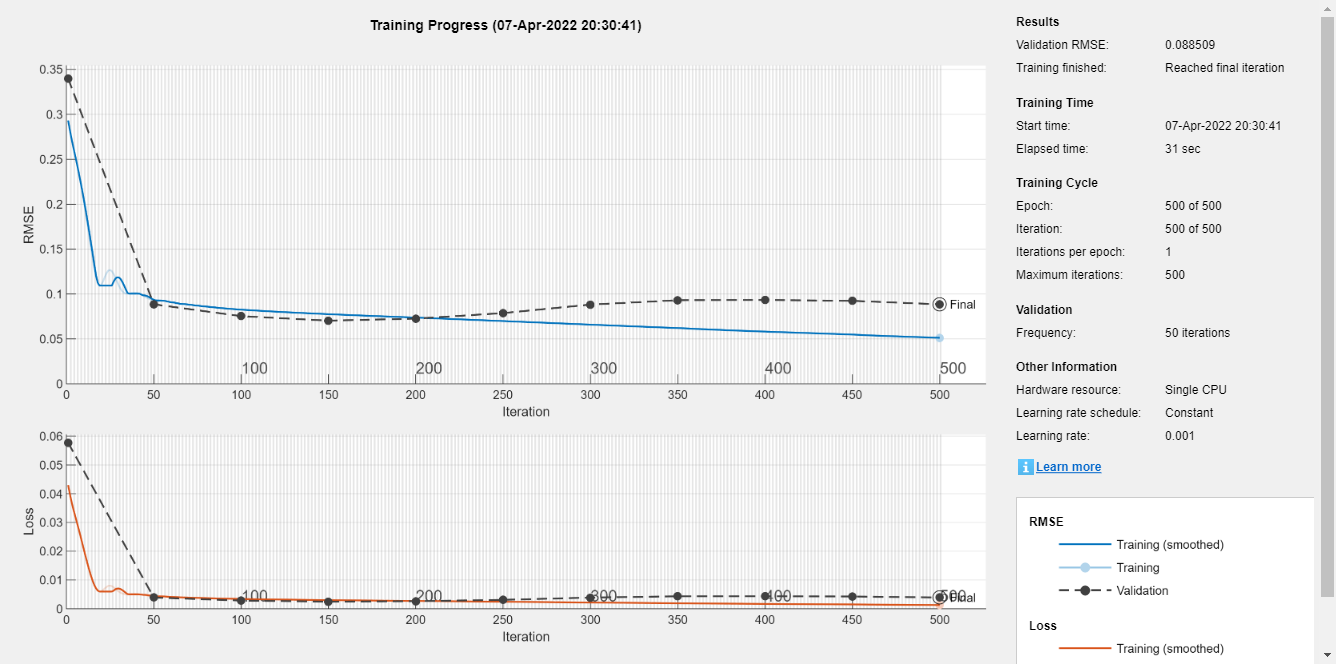

input_size = 100;
layerCNN1 = [
    imageInputLayer([1, input_size]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(xnorm', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(ynorm);
tbl = table(cellx);
tbl.cellyB = cellyB;

if bTrainingWithValidation
    Traintbl = tbl(tr.trainInd, :);
    valtbl = tbl(tr.valInd, :);
    testtbl = tbl(tr.testInd, :);
    
    options = trainingOptions('adam', ...
     'InitialLearnRate', 0.001, ...
     'MaxEpochs',500, ...
     'MiniBatchSize',50, ...
     'Plots','training-progress', 'ValidationData', valtbl);
     netCNN1 = trainNetwork(Traintbl, layerCNN1, options);

else
    options = trainingOptions('adam', ...
        'InitialLearnRate', 0.001, ...
        'MaxEpochs',500, ...
        'MiniBatchSize',50, ...
        'Plots','training-progress');
    netCNN1 = trainNetwork(tbl, layerCNN1, options);
end


%


- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:08 |         0.36 |         0.36 |       0.0631 |       0.0649 |          0.0010 |
|      50 |          50 |       00:00:14 |         0.09 |         0.07 |       0.0037 |       0.0025 |          0.0010 |
|     100 |         100 |       00:00:18 |         0.07 |         0.06 |       0.0027 |       0.0015 |          0.0010 |
|     150 |         150 |       00:00:29 |         0.07 |         0.06 |       0.0022 |   

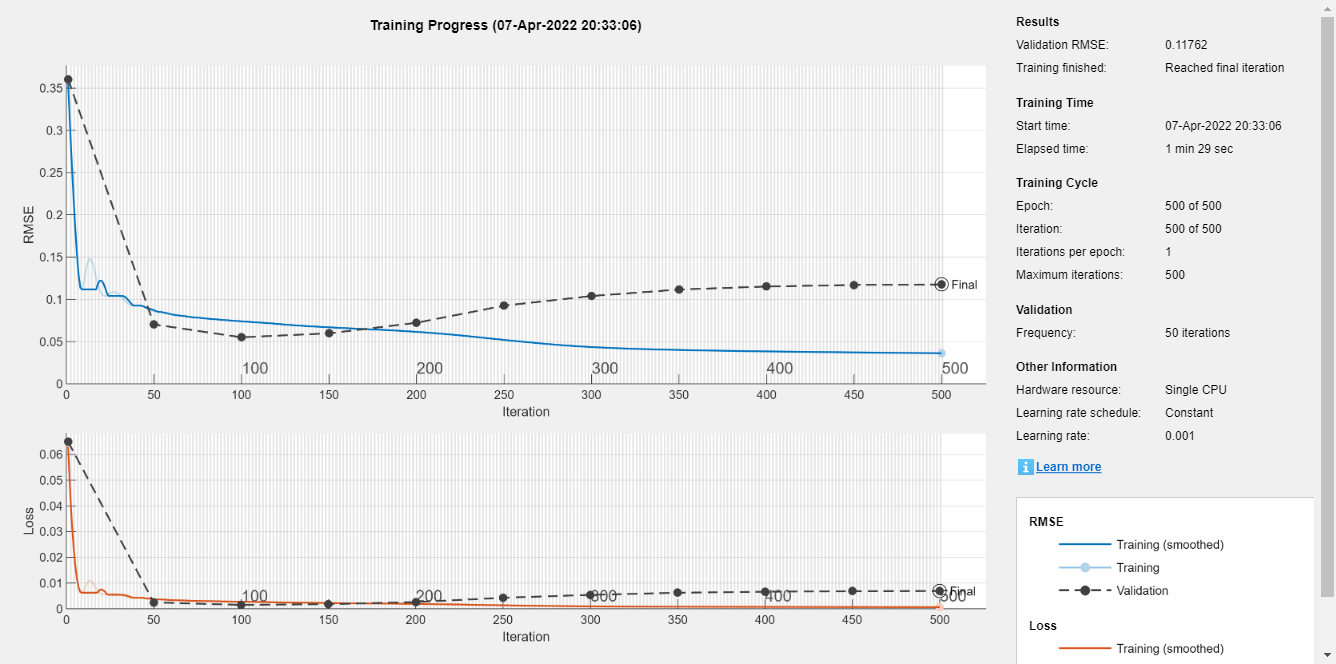

layerCNN2 = [
    imageInputLayer([1, input_size]);
    convolution2dLayer([1, 2], 30, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 15, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
if bTrainingWithValidation
    netCNN2 = trainNetwork(Traintbl, layerCNN2, options);
else
    netCNN2 = trainNetwork(tbl, layerCNN2, options);
end

- LSTM : 1 lstm layer with 5 hidden units

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |         0.34 |         0.28 |       0.0584 |       0.0397 |          0.0010 |
|      50 |          50 |       00:00:14 |         0.10 |         0.12 |       0.0047 |       0.0074 |          0.0010 |
|     100 |         100 |       00:00:17 |         0.09 |         0.10 |       0.0041 |       0.0052 |          0.0010 |
|     150 |         150 |       00:00:21 |         0.09 |         0.09 |       0.0036 |       0.0038 |          0.0010 |
|     20

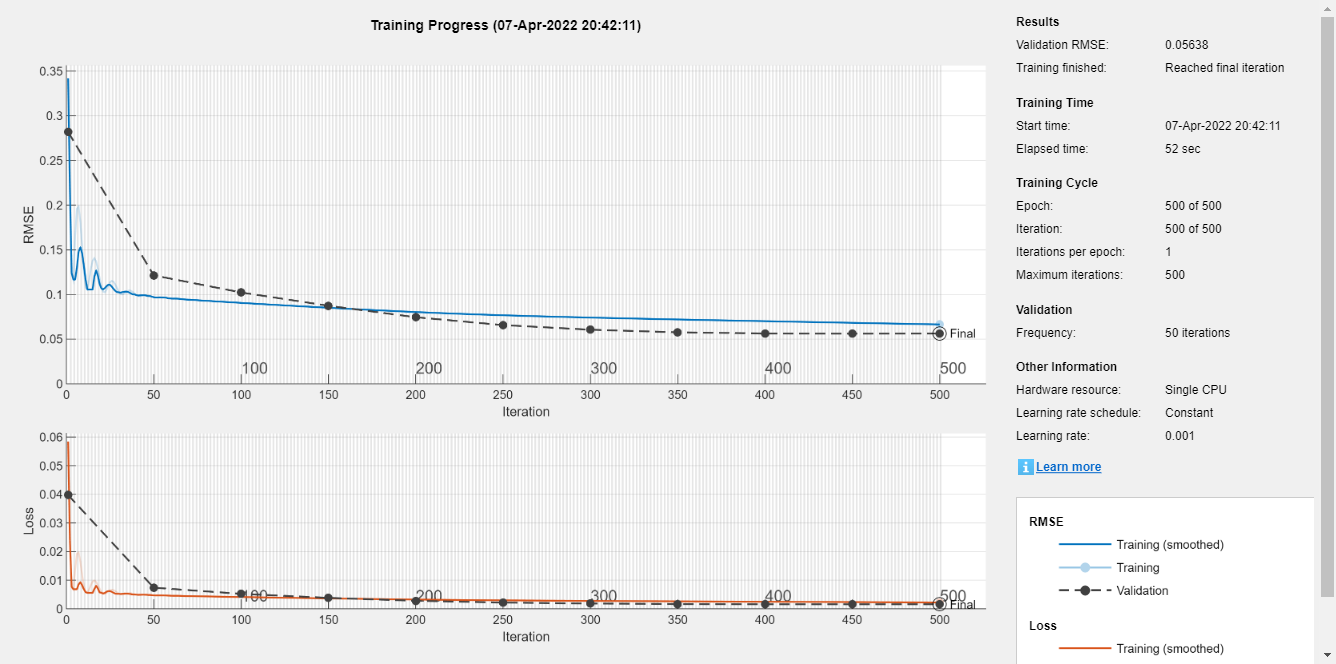

numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(input_size)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(xnorm', 1)';
cellyB = num2cell(ynorm);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

if bTrainingWithValidation
 options = trainingOptions('adam', ...
     'InitialLearnRate', 0.001, ...
     'MaxEpochs',500, ...
     'MiniBatchSize',50, ...
     'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

    netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

else
    options = trainingOptions('adam', ...
        'InitialLearnRate', 0.001, ...
        'MaxEpochs',500, ...
        'MiniBatchSize',50, ...
        'Plots','training-progress');

    netLSTM = trainNetwork(cellx, cellyB, layersLSTM, options);
end 

ryan2_gen_data_model_desc = 'ryan2_gen_data_model';
save('ryan2_gen_data_model.mat','ryan2_gen_data_model_desc');
save('ryan2_gen_data_model.mat','netFNN10' ,'-append')
save('ryan2_gen_data_model.mat','netFNN' ,'-append')
save('ryan2_gen_data_model.mat','netCNN1' ,'-append')
save('ryan2_gen_data_model.mat','netCNN2' ,'-append')
save('ryan2_gen_data_model.mat','netLSTM' ,'-append')


if bTrainingWithValidation

### Prediciton using each 5 trained model

Make a prediction **using trained models**

- FNN10

pFNN10 = netFNN10(xnorm(tr.testInd, :)');

- FNN40

pFNN = netFNN(xnorm(tr.testInd, :)');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

cellx = num2cell(xnorm(tr.testInd, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);

x_4d = zeros(1, input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end
pCNN1 = predict(netCNN1, x_4d);

- CNN2 : 2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

pCNN2 = predict(netCNN2, x_4d);

- LSTM : 1 lstm layer with 100 hidden units

pLSTM = cell2mat(predict(netLSTM, num2cell(xnorm(tr.testInd, :)', 1)));

Denormalization for graphical ouput. Multiplying the range of original and add minimum value.

y_real = ynorm(tr.testInd, :)*yrate + ymin;
pFNN10_hat = pFNN10*yrate+ ymin;
pFNN_hat = pFNN*yrate + ymin;
pCNN1_hat = pCNN1*yrate + ymin;
pCNN2_hat = pCNN2*yrate + ymin;
pLSTM_hat = pLSTM*yrate + ymin;

### Result visualization

Visualize the prediction result. Battery capacity estimation based multi-channel charing profiles, using Voltage, Current and temperature.

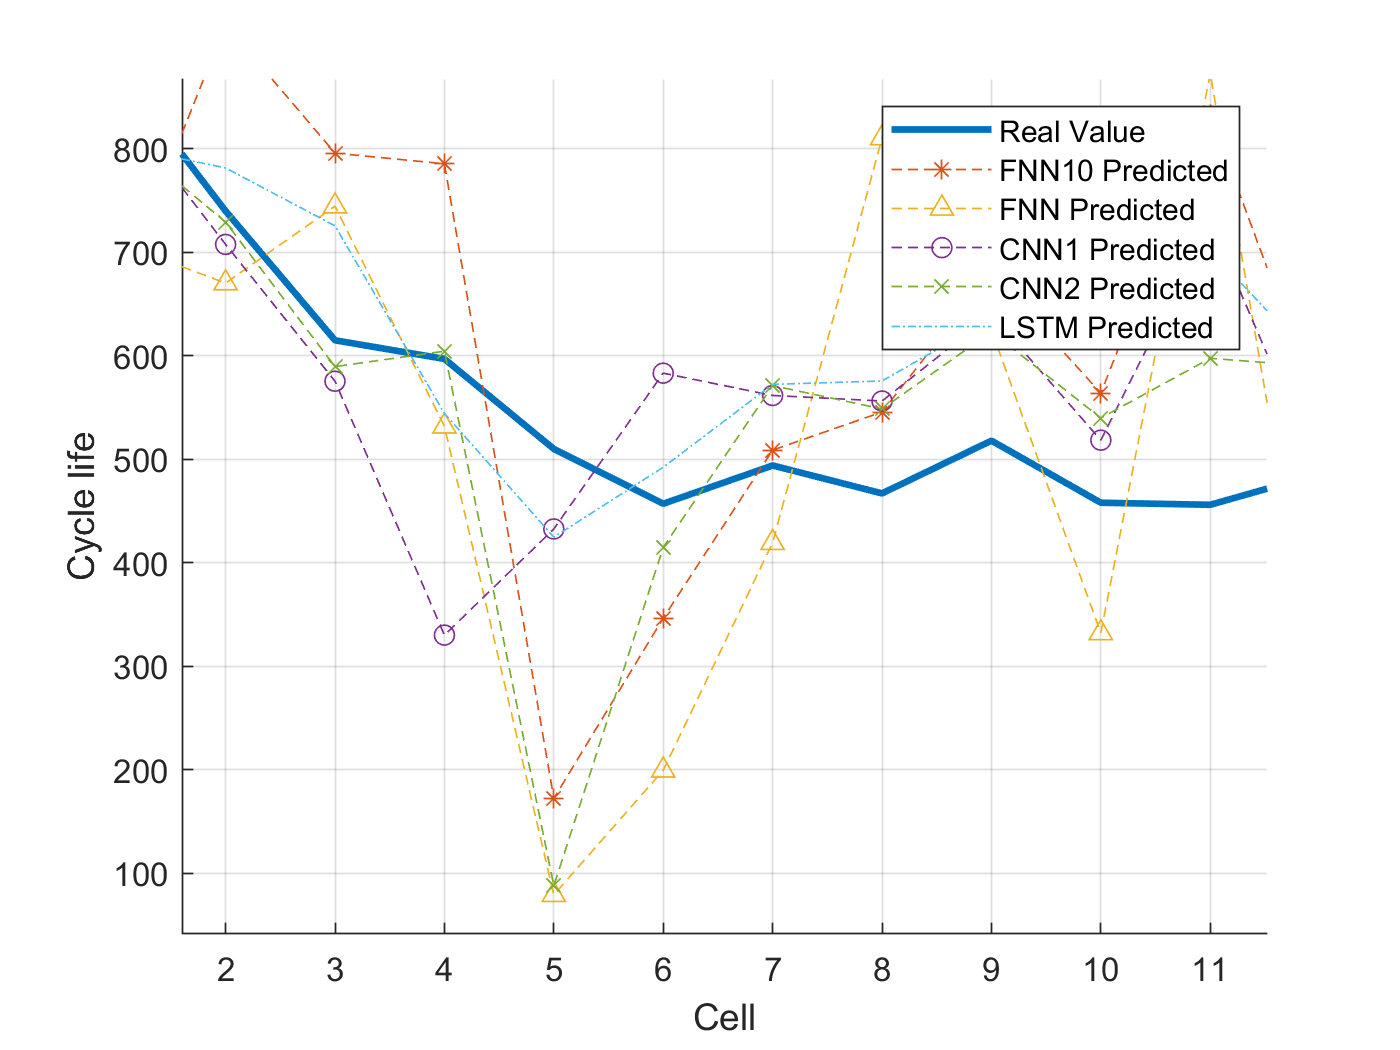

figure, hold on, grid on,
plot(y_real, 'linewidth', 2), plot(pFNN10_hat, '*--'), plot(pFNN_hat, '^--'), plot(pCNN1_hat, 'o--'), plot(pCNN2_hat, 'x--'), plot(pLSTM_hat, '-.')
%plot(1:25, 1.4*ones(1, 25),'k--','LineWidth', 2), xlim([1 25])
%title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cell
ylabel 'Cycle life'
legend('Real Value', 'FNN10 Predicted', 'FNN Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted')

RMSE

rmse_pFNN10 = sqrt(mean(( y_real' - pFNN10_hat ).^2))

rmse_pFNN10 = 197.1000

rmse_pFNN = sqrt(mean(( y_real' - pFNN_hat ).^2))

rmse_pFNN = 238.3507

rmse_pCNN1  = sqrt(mean(( y_real' - pCNN1_hat' ).^2))

rmse_pCNN1 = single
130.0017

rmse_pCNN2  = sqrt(mean(( y_real' - pCNN2_hat' ).^2))

rmse_pCNN2 = single
143.1129

rmse_pLSTM  = sqrt(mean(( y_real' - pLSTM_hat' ).^2))

rmse_pLSTM = single
120.8043

end

ytestnorm_hat_netFNN10 = netFNN10(xtestnorm');
ytestnorm_hat_netFNN = netFNN(xtestnorm');

total_cycle = length(ytestnorm_hat_netFNN);
cellx = num2cell(xtestnorm', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, x_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end
ytestnorm_hat_netCNN1 = predict(netCNN1, x_4d);
ytestnorm_hat_netCNN2 = predict(netCNN2, x_4d);
ytestnorm_hat_netLSTM = cell2mat(predict(netLSTM, num2cell(xtestnorm', 1)));

ytest_real = ytestnorm*yrate + ymin;
ytest_hat_netFNN10 = ytestnorm_hat_netFNN10*yrate + ymin;
ytest_hat_netFNN = ytestnorm_hat_netFNN*yrate + ymin;
ytest_hat_netCNN1 = ytestnorm_hat_netCNN1*yrate + ymin;
ytest_hat_netCNN2 = ytestnorm_hat_netCNN2*yrate + ymin;
ytest_hat_netLSTM = ytestnorm_hat_netLSTM*yrate + ymin;

RMSE

rmse_ytest_hat_netFNN10 = sqrt(mean(( ytest_real' - ytest_hat_netFNN10 ).^2))

rmse_ytest_hat_netFNN10 = 526.4097

rmse_ytest_hat_netFNN = sqrt(mean(( ytest_real' - ytest_hat_netFNN ).^2))

rmse_ytest_hat_netFNN = 414.6143

rmse_ytest_hat_netCNN1 = sqrt(mean(( ytest_real' - ytest_hat_netCNN1' ).^2))

rmse_ytest_hat_netCNN1 = single
510.8833

rmse_ytest_hat_netCNN2  = sqrt(mean(( ytest_real' - ytest_hat_netCNN2' ).^2))

rmse_ytest_hat_netCNN2 = single
527.8210

rmse_ytest_hat_netLSTM  = sqrt(mean(( ytest_real' - ytest_hat_netLSTM' ).^2))

rmse_ytest_hat_netLSTM = single
506.8488

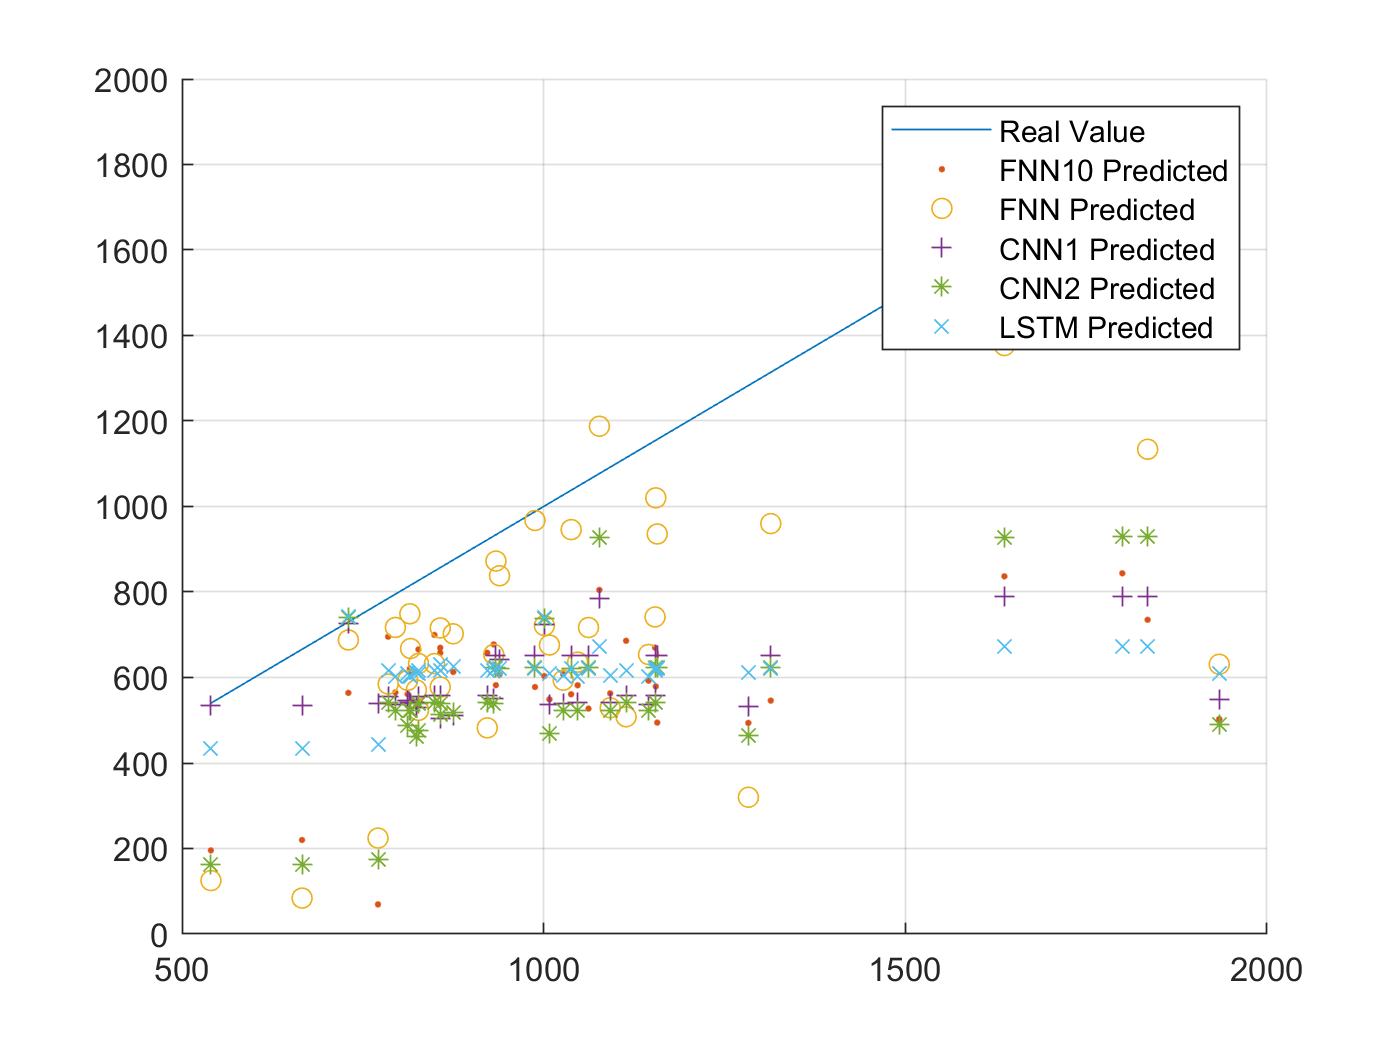

ytest_hat_netFNN = ytestnorm_hat_netFNN*yrate + ymin;
figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,ytest_hat_netFNN10,'.')
plot(ytest,ytest_hat_netFNN,'o')
plot(ytest,ytest_hat_netCNN1,'+')
plot(ytest,ytest_hat_netCNN2,'*')
plot(ytest,ytest_hat_netLSTM,'x')
hold off
legend('Real Value', 'FNN10 Predicted', 'FNN Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted')

여기까지


%%%%%%%%%%%% 학습한 데이타로 검증
ynorm_hat_netFNN = netFNN(xnorm')';
total_cycle = length(ynorm_hat_netFNN);
y_hat_netFNN = ynorm_hat_netFNN*yrate + ymin;
figure, hold on, grid on,
plot(y,y_hat_netFNN,'x')
hold off
%{
ynorm_hat_netFNN = netFNN(xnorm(tr.testInd, :)')';
total_cycle = length(ynorm_hat_netFNN);
y_hat_netFNN = ynorm_hat_netFNN*yrate + ymin;
figure, hold on, grid on,
plot(y(tr.testInd),y_hat_netFNN,'x')
hold off
%}
%%%%%%%%%%%%%

ytestnorm_hat_netFNN = netFNN(xtestnorm')';
total_cycle = length(ytestnorm_hat_netFNN);
cellx = num2cell(xtestnorm', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, x_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

ytest_hat_netFNN = ytestnorm_hat_netFNN*yrate + ymin;
figure, hold on, grid on,
plot(ytest,ytest_hat_netFNN,'x')
hold off


CNN을 위해 충전전류를 2차원 이미지로 만들기

ynormall,ymax,ymin,yrate,xnormall,xmax,xmin,xrate

a = xtestnorm(1,:)
b = zeros(100,100);
c = round(xtestnorm(1,:)* 100)
for i=1:100
    b(i,c(i)+1)=1;
end
b

xxx = [1:100]

space = [ 1:100]
new_space = [1:28]
new_xxx = interp1(space,xxx,new_space,'linear')
figure
plot(new_xxx)



plot_max_x = 28;
plot_max_y = 28 ;

%a = 
%x = 
xx_max = 28
y_max = 28
rows = max(xtestnorm(1,:));
columns = length(yo);
outputImage = false(rows, columns);
for k = 1 : columns
  outputImage(yo(k), k) = true;
end
imshow(outputImage);
